# Realizations of Multivariate RVs

Note: this script reproduces the opening figure of Chapter 3 of **Statistics for Chemical Engineers**: four data sets that show different relationships between two RVs. Victor Z UW-Madison, 2019 examples of multivariate datasets

clc; clear all; close all hidden; format short;

## Data set 1

data set 1

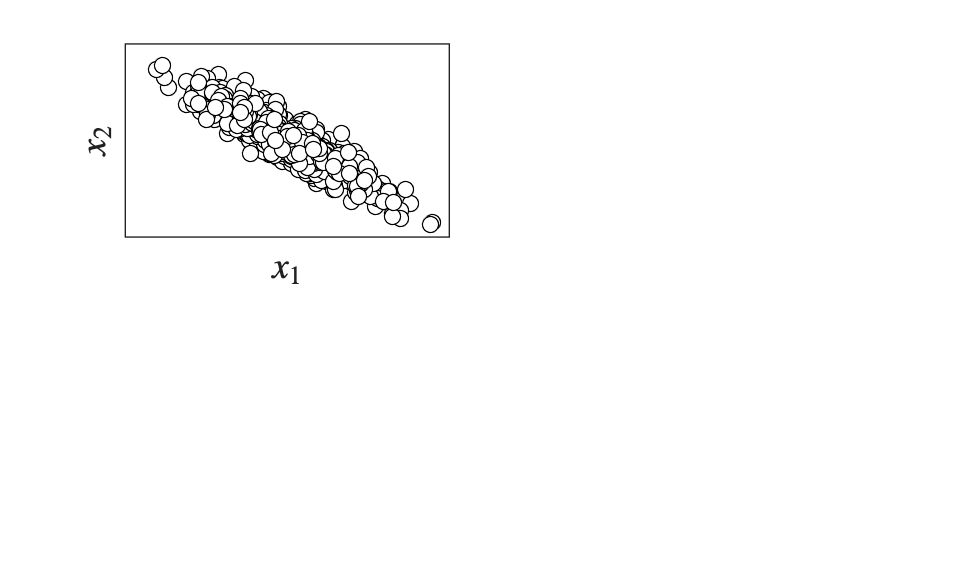

mu = [0 0];
Sigma = [1 -0.9; -0.9 1]; % anticorrelated

rng(0)
nsample = 1000; % number of random samples
sample = mvnrnd(mu,Sigma,nsample); % collect samples

figure(1); 
subplot(2,2,1)
plot(sample(:,1),sample(:,2),'blacko','MarkerFaceColor','w'); % plot samples
grid on
xlabel('$x_1$','Interpreter','latex','FontSize',14)
ylabel('$x_2$','Interpreter','latex','FontSize',14)
set(gca,'xtick',[],'ytick',[])

## Data set 2

data set 2

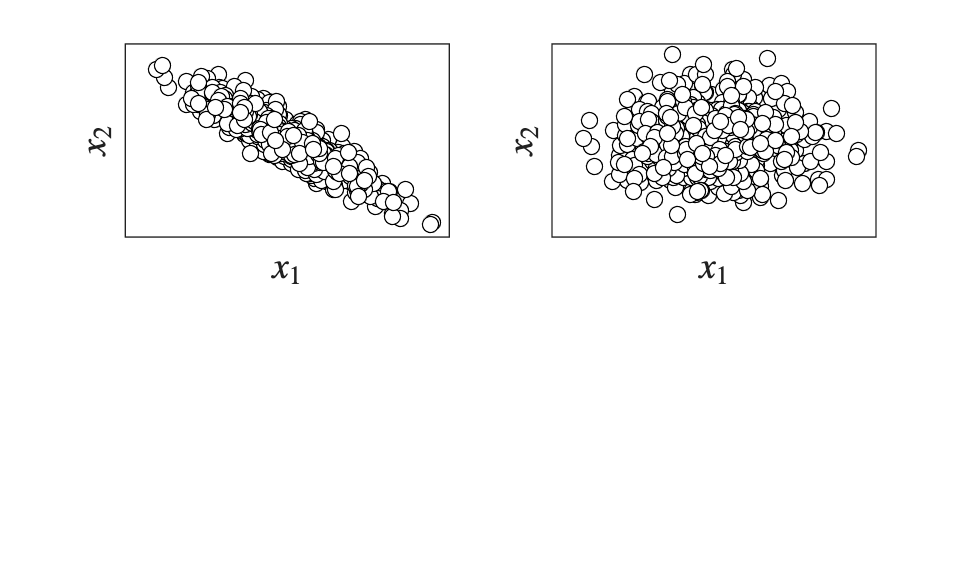

mu = [0 0];
Sigma = [1 0; 0 1]; % anticorrelated

rng(0)
nsample = 1000; % number of random samples
sample = mvnrnd(mu,Sigma,nsample); % collect samples

figure(1); 
subplot(2,2,2)
plot(sample(:,1),sample(:,2),'blacko','MarkerFaceColor','w'); % plot samples
grid on
xlabel('$x_1$','Interpreter','latex','FontSize',14)
ylabel('$x_2$','Interpreter','latex','FontSize',14)
set(gca,'xtick',[],'ytick',[])

## Data set 3

data set 3

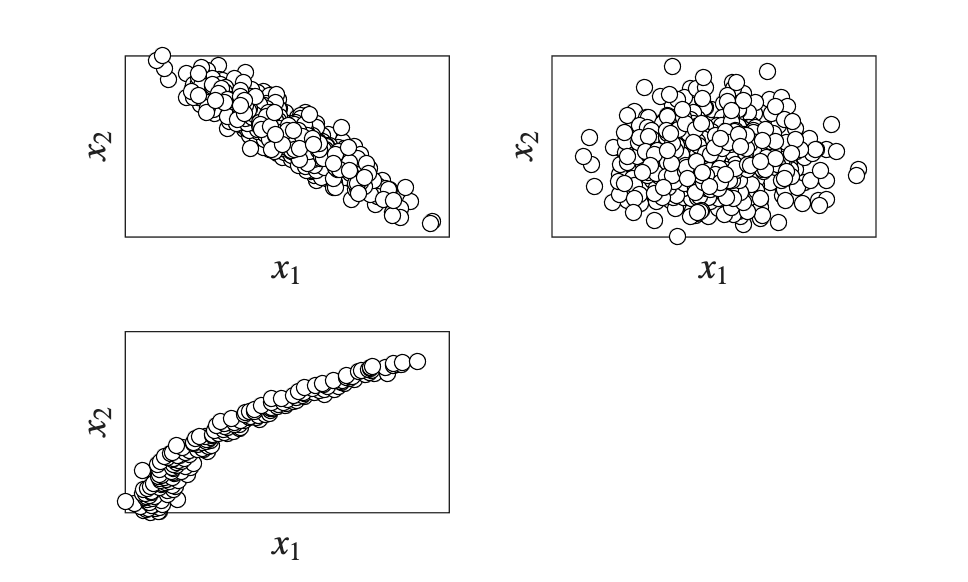

nsample=200;
x1=linspace(0,5,nsample)';
x2=x1.^2 + normrnd(0,1,nsample,1);

figure(1);
subplot(2,2,3)
plot(x2,x1,'blacko','MarkerFaceColor','w'); % plot samples
xlabel('$x_1$','Interpreter','latex','FontSize',14)
ylabel('$x_2$','Interpreter','latex','FontSize',14)
grid on
set(gca,'xtick',[],'ytick',[])

## Data set 4

data set 4

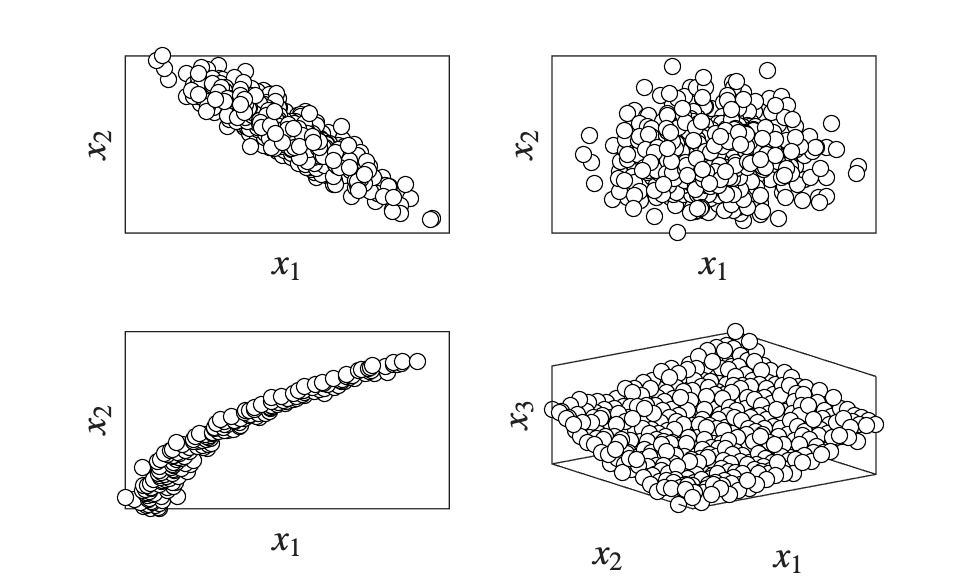

rng(0)
[x1,x2] = meshgrid(0:0.5:10);
x3 = 2*x1.^2 + 2*x2.^2 + 20*normrnd(0,1,21);

% plot the ellipse and the samples
figure(1); 
subplot(2,2,4)
plot3(x1,x2,x3,'blacko','MarkerFaceColor','w'); % plot samples
xlabel('$x_1$','Interpreter','latex','FontSize',14)
ylabel('$x_2$','Interpreter','latex','FontSize',14)
zlabel('$x_3$','Interpreter','latex','FontSize',14)
grid on
box on
set(gca,'xtick',[],'ytick',[],'ztick',[])
print -depsc -r300 ch3_example_3d_data.eps

## Note

Multivariate RVs can be independent, linearly related (positively or negatively), or related in nonlinear ways; the joint pdf captures these relationships.